# Reconeixement

## Training

% Define the base folder path
baseFolder = './Train/';

% Get all subfolders matching the pattern
folderPattern = fullfile(baseFolder, '*', 'TM');
folders = dir(folderPattern);

% Initialize a structure to store features for each model
modelFeatures = struct();

numBins = 16; % Adjust number of bins as needed

% Loop through each folder
for i = 1:length(folders)
    % Get the current "TM" folder
    currentFolder = fullfile(folders(i).folder, folders(i).name);
    
    % Extract the name of the model from the parent path
    [parentPath, ~, ~] = fileparts(currentFolder); % Get parent path
    [modelName, ~, ~] = fileparts(parentPath);    % Get folder name before "TM"
    [~, modelName, ~] = fileparts(modelName);     % Further clean up the model name
    modelName = strrep(modelName, " ", "_");      % Replace spaces with underscores
    
    % Get all subfolders within "TM" to treat as submodels
    submodels = dir(currentFolder);
    submodels = submodels([submodels.isdir]);    % Keep only directories
    submodels = submodels(~ismember({submodels.name}, {'.', '..'})); % Exclude '.' and '..'
    
    % Process each submodel folder
    for sub = 1:length(submodels)
        submodel = submodels(sub).name;
        submodelPath = fullfile(currentFolder, submodel); % Path to the submodel folder
               
        % Check if the path is a folder and contains images
        if ~isempty(dir(fullfile(submodelPath, '*.jpg'))) % Only process if there are images
    
            % Initialize storage for the current submodel
            modelFeatures.(modelName).(submodel).keypointsSURF = {};
            modelFeatures.(modelName).(submodel).keypointsSIFT = {};
            modelFeatures.(modelName).(submodel).corners = {};
            modelFeatures.(modelName).(submodel).rgHistograms = {};
            modelFeatures.(modelName).(submodel).rgMin = {};
            modelFeatures.(modelName).(submodel).im = {};

            % Get all images in the current submodel folder
            imageFiles = dir(fullfile(submodelPath, '*.jpg')); % Adjust extension if needed
            
            % Process each image
            for j = 1:length(imageFiles)
                % Get the image file path and load it
                imagePath = fullfile(imageFiles(j).folder, imageFiles(j).name);
                img = imread(imagePath);
                
                % Convert image to grayscale for keypoint detection
                grayImg = rgb2gray(img);
                
                % SURF keypoints
                keypointsSURF = detectSURFFeatures(grayImg);
                modelFeatures.(modelName).(submodel).keypointsSURF{end+1} = keypointsSURF;
                
                % FAST corners
                corners = detectFASTFeatures(grayImg);
                modelFeatures.(modelName).(submodel).corners{end+1} = corners;
                
                % SIFT keypoints
                kpSIFT = detectSIFTFeatures(grayImg);
                [featSIFT, kpSIFT] = extractFeatures(grayImg, kpSIFT);
                modelFeatures.(modelName).(submodel).keypointsSIFT{end+1} = kpSIFT;

                % Compute the normalized RG histogram
                img = im2double(img); % Ensure values are in [0, 1]
                R = img(:, :, 1);
                G = img(:, :, 2);
                B = img(:, :, 3);
                RG = R ./ (R + G + B + eps);
                GG = G ./ (R + G + B + eps);
                
                % Compute histogram
                [rgHist, ~] = hist3([RG(:), GG(:)], [numBins, numBins]);
                
                % Normalize histogram
                rgHist = rgHist / sum(rgHist(:));
                modelFeatures.(modelName).(submodel).rgHistograms{end+1} = rgHist;
                modelFeatures.(modelName).(submodel).im{end+1} = img;
            end
            
            % Compute the blanket histogram
            blanket = ones(numBins) * 255;
            for k = 1:length(modelFeatures.(modelName).(submodel).rgHistograms)
                A = modelFeatures.(modelName).(submodel).rgHistograms{k};
                blanket = min(blanket, A);
            end
            
            mx = double(1 / max(blanket(:)));
            blanket = blanket .* mx;
            modelFeatures.(modelName).(submodel).rgMin{end+1} = blanket;
        end
    end
end

clear A B R G GG RG ans blanket i j k modelName mx t img baseFolder currentFolder df_norm numBins rgHist folders folderPattern grayImg imageFiles imagePath keypointsSURF corners kpSIFT parentPath featSIFT sub submodel submodelPath submodels;




## Mostres SURF + FAST & SIFT + FAST

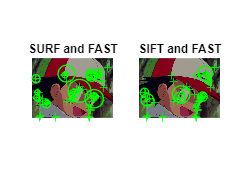

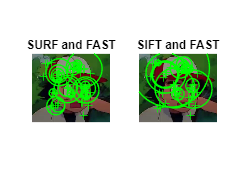

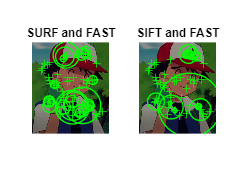

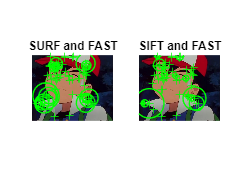

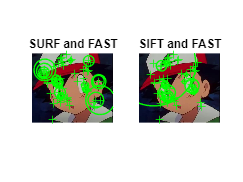

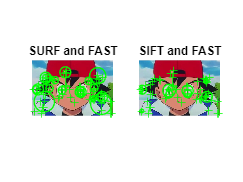

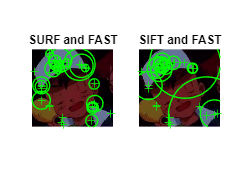

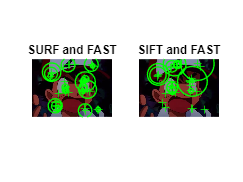

for i = 1:length(modelFeatures.pokemon.Cara.im)
    figure;subplot(1, 2, 1);imshow(modelFeatures.pokemon.Cara.im{i}); % Display image
    hold on;
    keys = modelFeatures.pokemon.Cara.keypointsSURF{i};
    corners = modelFeatures.pokemon.Cara.corners{i};
    plot(selectStrongest(keys,20),"ShowScale",true);
    plot(corners.selectStrongest(50));
    title('SURF and FAST');

    %for SIFT+FAST
    subplot(1, 2, 2);imshow(modelFeatures.pokemon.Cara.im{i}); % Display image
    hold on;
    keys = modelFeatures.pokemon.Cara.keypointsSIFT{i};
    plot(selectStrongest(keys,20),"ShowScale",true);
    plot(corners.selectStrongest(50));
    title('SIFT and FAST');
end

clear i keys keysx keysy;


## RANSAC

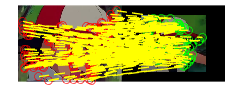

pairkeys=matchFeatures(modelFeatures.pokemon.Cara.keypointsSURF{1}.Location,modelFeatures.pokemon.Cara.keypointsSURF{2}.Location,"MatchThreshold",10);
paircorners=matchFeatures(modelFeatures.pokemon.Cara.corners{1}.Location,modelFeatures.pokemon.Cara.corners{2}.Location,"MatchThreshold",10);
matchedPoints1=modelFeatures.pokemon.Cara.keypointsSURF{1}.Location(pairkeys(:,1),:);
matchedPoints2=modelFeatures.pokemon.Cara.keypointsSURF{2}.Location(pairkeys(:,2),:);

matchedPoints1= [matchedPoints1; modelFeatures.pokemon.Cara.corners{1}.Location(paircorners(:,1),:)];
matchedPoints2= [matchedPoints2; modelFeatures.pokemon.Cara.corners{2}.Location(paircorners(:,2),:)];

I1 = modelFeatures.pokemon.Cara.im{1};
I2 = modelFeatures.pokemon.Cara.im{2};

[fLMedS,inliers] = estimateFundamentalMatrix(matchedPoints1,matchedPoints2, ...
    'NumTrials',5000);

figure;
showMatchedFeatures(I1,I2,matchedPoints1,matchedPoints2,"montage",PlotOptions=["ro","go","y--"]);
title("Putative Point Matches");

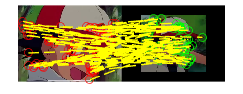


figure;
showMatchedFeatures(I1,I2,matchedPoints1(inliers,:),matchedPoints2(inliers,:),"montage",PlotOptions=["ro","go","y--"]);
title("Point Matches After Outliers Are Removed");


% Compute epipolar lines
epiLines = epipolarLine(fLMedS, matchedPoints2);

% Check distances from epipolar lines
% Extract the coefficients of the epipolar lines
a = epiLines(:, 1); % Coefficient of x
b = epiLines(:, 2); % Coefficient of y
c = epiLines(:, 3); % Constant term

% Compute distances from points in the second image to the epipolar lines
x = matchedPoints2(:, 1); % x-coordinates of points in the second image
y = matchedPoints2(:, 2); % y-coordinates of points in the second image

distances = abs(a .* x + b .* y + c) ./ sqrt(a.^2 + b.^2);
validMask = distances < 2; % Adjust threshold

% Filter matches
filteredPoints1 = matchedPoints1(validMask, :);
filteredPoints2 = matchedPoints2(validMask, :);

[fLMedS,inliers] = estimateFundamentalMatrix(filteredPoints1,filteredPoints2, ...
    'NumTrials',5000);

figure;
showMatchedFeatures(I1,I2,filteredPoints1,filteredPoints2,"montage",PlotOptions=["ro","go","y--"]);
title("Putative Point Matches");

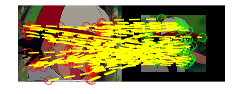


figure;
showMatchedFeatures(I1,I2,filteredPoints1(inliers,:),filteredPoints2(inliers,:),"montage",PlotOptions=["ro","go","y--"]);
title("Point Matches After Outliers Are Removed");